# Fault Detection 

## Description and Mathematical Model of the Experiment

The goal of this experiment is to validated the modeled equation when artificial fault introduced in the experiment.  The validation experiment involves all three tanks connected, Tank 1,2&3, by linking pipe and pressure sensor at each tank. Including pump input 1 & 2 at tank 1 and 3, respectively. And then a leak has been introduced which goes out from the tanks. Let $h^{1}_{k}$, $h^{2}_{k}$ and $h^{3}_{k}$ be the height levels of Tank 1, 2 & 3 respectively, at time instant $k$. The difference equation of the tank's height is as follows:


$$h^{1}_{k+1}=h^{1}_{k}+A_{1}\cdot sign\left(h^{2}_{k}-h^{1}_{k}\right)\sqrt{ \left|h^{2}_{k}-h^{1}_{k}\right| }+C_1\cdot u^{1}_{k}-B_1\cdot \sqrt{\left|h^{1}_{k}| \\

h^{2}_{k+1}=h^{2}_{k}-A_{1}\cdot sign\left(h^{2}_{k}-h^{1}_{k}\right)\sqrt{ \left|h^{2}_{k}-h^{1}_{k}\right| }-A_{2}\cdot sign\left(h^{2}_{k}-h^{3}_{k}\right)\sqrt{ \left|h^{2}_{k}-h^{3}_{k}\right|} -B_2\cdot \sqrt{\left|h^{2}_{k}|\\

h^{3}_{k+1}=h^{3}_{k}+A_{2}\cdot sign\left(h^{2}_{k}-h^{3}_{k}\right)\sqrt{ \left|h^{2}_{k}-h^{3}_{k}\right| }+C_2\cdot u^{2}_{k} -B_3\cdot \sqrt{\left|h^{3}_{k}|\\$$


### When Tank1&2 Leakage Activated

% Tanks %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Tank 1
pressure1 = xlsread('3_pressure_sensor_tank1');
colpressure1 = pressure1(:,11);
height1_m = 0.2849*(colpressure1) + 0.0547;

% Tank 2
pressure2 = xlsread('3_pressure_sensor_tank2');
colpressure2 = pressure2(:,11);
height2_m = 0.2866*(colpressure2) + 0.0608;

% Tank 3
pressure3 = xlsread('3_pressure_sensor_tank3');
colpressure3 = pressure3(:,11);
height3_m = 0.2806*(colpressure3) + 0.0654;


`pressurei`, where i=1,2,3, are the data obtained from Labview for pressure sensor i (11 columns)

`colpressurei`, where i=1,2,3, are the pressure data (voltage) of sensor i (11th column of `pressurei`)

`heighti_m`, where i=1,2,3, is the height of Tank i based on the previously identified *pressure-to-height* linear map of pressure sensor i


time = length(height1_m);

% Pumps %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pump 1
pump1 = xlsread('3_PWM_duty_tank1');
u1 = normalize(pump1(:,5),'range');

%Pump 2
pump2 = xlsread('3_PWM_duty_tank3');
u2 = normalize(pump2(:,5),'range');


`pumpi`, where i=1,2, are the PMW ducty cycle data for *pump i*.

`ui`, where i=1,2, is the normalized PWM duty cycle of *pump i*, such that `ui` $\in \left\lbrack 0\;1\right\rbrack$.

% Flow Meters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Tank 1 leakage
leak1 = xlsread('3_pulses_counted_leakage_tank1');
flow1 = leak1(:,5);
flowrate1 = zeros(time-1,1); % Flow Meter Pulses
for i=1:time-1
    flowrate1(i) = flow1(i+1) - flow1(i); % Flow Meter Delta
end

% Tank 2 leakage
leak2 = xlsread('3_pulses_counted_leakage_tank2');
flow2 = leak2(:,5);           % Flow Meter Pulses
flowrate2 = zeros(time-1,1);
for i=1:time-1
    flowrate2(i) = flow2(i+1) - flow2(i); % Flow Meter Delta
end

%Here we find the time instances when the two leaks appear
L1_t_index=find(flow1);
L1_time=L1_t_index(1);

L2_t_index=find(flow2);
L2_time=L2_t_index(2);


`flowi`, where i=1,2, is the leak flow meter's measurment (pulses/sec) of *Tank i.*

`Li_time`, where i=1,2, is the first non zero element of the array` flowi`, indicating the leak time occurence of T*ank i*.


fig1=figure(1)

fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


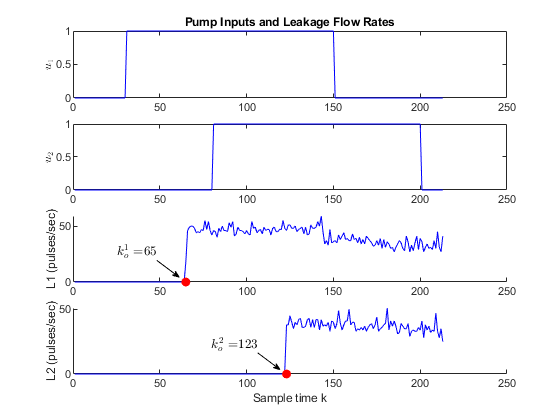

clf(fig1,'reset');
cla(fig1,'reset');
subplot(4,1,1)
plot(1:time,u1,'-b')
title('Pump Inputs and Leakage Flow Rates')
ylabel('$u_{1}$','Interpreter',"latex")
subplot(4,1,2)
plot(1:time,u2,'-b')
ylabel('$u_{2}$','Interpreter',"latex")
subplot(4,1,3)
hold on
plot(1:time,flow1,'-b')
plot(L1_time,0,'o','MarkerEdgeColor','red',"MarkerFaceColor",'red')
hold off
annotation('textarrow',[0.28 0.32],[0.38 0.34],...
            'String',['$k_{o}^1=$' num2str(L1_time)],...
             'HeadLength',5,'HeadWidth',5,'Interpreter',"latex")
ylabel('L1 (pulses/sec)')
subplot(4,1,4)
hold on
plot(1:time,flow2,'-b')
plot(L2_time,0,'o','MarkerEdgeColor','red',"MarkerFaceColor",'red')
hold off
annotation('textarrow',[0.46 0.5],[0.16 0.12],...
            'String',['$k_{o}^2=$' num2str(L2_time)],...
             'HeadLength',5,'HeadWidth',5,'Interpreter',"latex")
ylabel('L2 (pulses/sec)')
xlabel('Sample time k')

The following Section involves the validation of the model. We use two ways of validation:

- One-step (O-S) prediction: The right-hand side of the difference equation is calculated from the experimentalm data; thus, the state variables at time instant $k$ are predicted based on the experimental values of the state and the input at the time instant $k-1$.

- Initical Conditions (IC) only prediction: The values of the state variables are predicted solely by the identified model and the initial conditions of the system (obtained by the experimental data). Because no recent data are used, the error is progressively accumulated in the predicted states.

**What should be changed for the estimation/detection code? **The IC model is more convinient for the estimation/detection part. The leak fault modes should be multiplied with the binary variable that represents the health of the system (the "B-terms"). 

fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


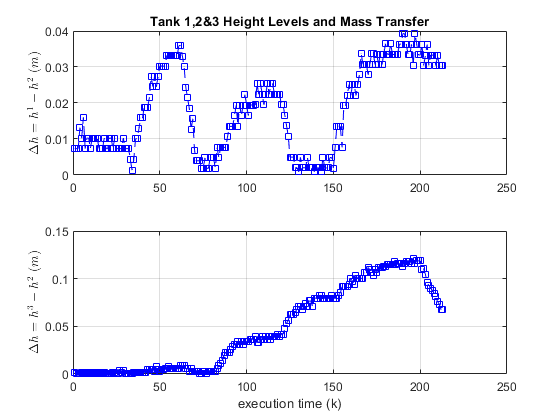

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%For simplicity in the calculations, we compute the heigh differences between Tank 1 & 2 and
%Tank 2 & 3, respectively
delta_height1 = zeros(time-1,1);
 for i=1:time-1
     delta_height1(i) = height2_m(i)-height1_m(i);
 end
 
  mass_flow_m1 = sign(delta_height1).*sqrt( abs(delta_height1) );


delta_height2 = zeros(time-1,1);
 for i=1:time-1
     delta_height2(i) = height2_m(i)-height3_m(i);
 end
 
  mass_flow_m2 = sign(delta_height2).*sqrt( abs(delta_height2) );
  
%%%%%%% Coefficents
%%%%%%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A_1 = 0.0188;
A_2 = 0.0195;
B_1 = 0.0123;
B_2 = 0.0122;
C_1 = 0.0067;
C_2 = 0.0068; 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Left side is k+1--One-step prediction
  height1_o = zeros(time-1,1);
  height2_o = zeros(time-1,1);
  height3_o = zeros(time-1,1);
   for i = 1:time-1
       for j = 65:time-1
           for k = 122:time-1
         height1_o(i) = height1_m(i) + A_1*mass_flow_m1(i) + C_1*u1(i) - B_1*sqrt(abs(height1_m(j))); 
         height2_o(i) = height2_m(i) - A_1*mass_flow_m1(i) - A_2*mass_flow_m2(i) - B_2*sqrt(abs(height2_m(k)));
         height3_o(i) = height3_m(i) + A_2*mass_flow_m2(i) + C_2*u2(i); 
           end
       end     
   end
   
%Left side is k+1--I.C.-only prediction 
 height1_i = zeros(time-1,1);
 height1_i(1)=height1_m(1);
 
 height2_i = zeros(time-1,1);
 height2_i(1)=height2_m(1);
 
 height3_i = zeros(time-1,1);
 height3_i(1)=height3_m(1);
 for i=2:time
      for j = 65:time-1
           for k = 122:time-1
     height1_i(i) = height1_i(i-1) + A_1*mass_flow_m1(i-1) + C_1*u1(i-1) - B_1*sqrt(abs(height1_m(j))); 
     height2_i(i) = height2_i(i-1) - A_1*mass_flow_m1(i-1) - A_2*mass_flow_m2(i-1) - B_2*sqrt(abs(height2_m(k)));
     height3_i(i) = height3_i(i-1) + A_2*mass_flow_m2(i-1) + C_2*u2(i-1); 
           end
      end
 end
 
 
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 fig3=figure(3)

fig3 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


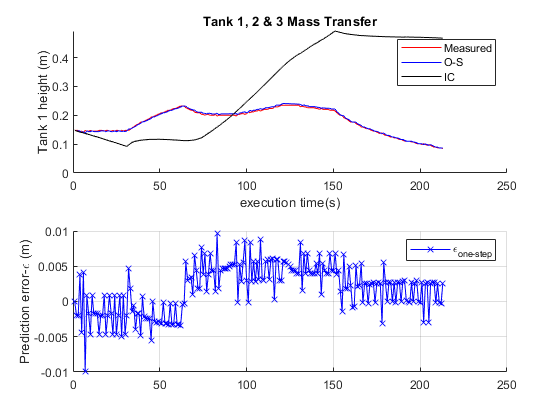

 clf(fig3,'reset');
 cla(fig3,'reset');
 subplot(2,1,1)
 hold on
 plot(height1_m,'-r')
 plot([height1_m(1); height1_o],'-b')
 plot(height1_i,'-k')
 hold off;
 title('Tank 1, 2 & 3 Mass Transfer')
 legend('Measured','O-S','IC')
 xlabel('execution time(s)')
 ylabel('Tank 1 height (m)')
 subplot(2,1,2)
 hold on
 plot([height1_m(1); height1_o]-height1_m,'-bx')
 %plot(height1_i-height1_m,'-kx')
 ylabel('Prediction error-\epsilon (m)')
 legend('\epsilon_{one-step}')%'\epsilon_{IC}')
 hold off
 grid on

        

 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 fig4=figure(4)

fig4 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


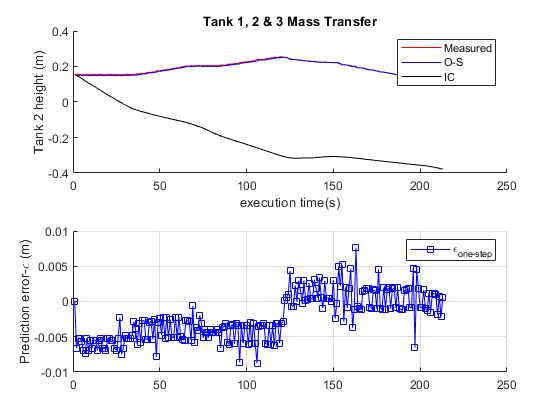

 clf(fig4,'reset');
 cla(fig4,'reset');
 subplot(2,1,1)
 hold on
 plot(height2_m,'-r')
 plot([height2_m(1); height2_o],'-b')
 plot(height2_i,'-k')
 hold off;
 title('Tank 1, 2 & 3 Mass Transfer')
 legend('Measured','O-S','IC')
 xlabel('execution time(s)')
 ylabel('Tank 2 height (m)')
 subplot(2,1,2)
 hold on
 plot([height2_m(1); height2_o]-height2_m,'-bs')
 %plot(height2_i-height2_m,'-kd')
 ylabel('Prediction error-\epsilon (m)')
 legend('\epsilon_{one-step}')%,'\epsilon_{IC}')
 hold off
 grid on

 
 
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 fig5=figure(5)

fig5 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


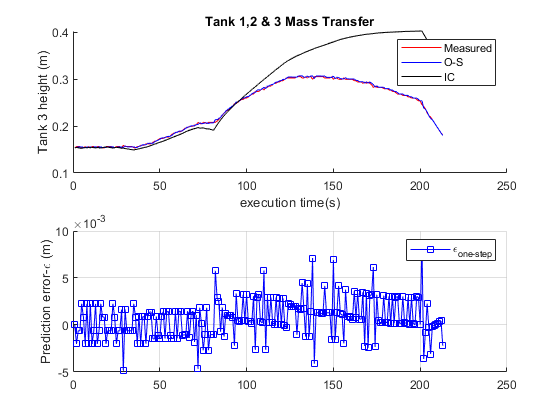

 clf(fig5,'reset');
 cla(fig5,'reset');
 subplot(2,1,1)
 hold on
 plot(height3_m,'-r')
 plot([height3_m(1); height3_o],'-b')
 plot(height3_i,'-k')
 hold off;
 title('Tank 1,2 & 3 Mass Transfer')
 legend('Measured','O-S','IC')
 xlabel('execution time(s)')
 ylabel('Tank 3 height (m)')
 subplot(2,1,2)
 hold on
 plot([height3_m(1); height3_o]-height3_m,'-bs')
 %plot(height2_i-height2_m,'-kd')
 ylabel('Prediction error-\epsilon (m)')
 legend('\epsilon_{one-step}')%,'\epsilon_{IC}')
 hold off
 grid on